# Simulation eines Räuber-Beute-Modells

Wir betrachten ein Beute-Räuber-Modell (siehe Buch) für $t \in [0,T]$:

$ y_1'=c_1 y_1(1-d_1 y_2), ~~y_1(0)=y_1^0
 $   ($y_1(t)$: Beute-Population zum Zeitpunkt $t$)

$ y_2'=c_2 y_2(d_2 y_1-1), ~~y_2(0)=y_2^0
 $   ($y_2(t)$: Räuber-Population zum Zeitpunkt $t$)

mit positiven Parametern $c_1,c_2,d_1,d_2$.

In diesem Matlabprogram wird dieses Modell mit dem verbesserten Euler-Verfahren (siehe Buch) diskretisiert.

Wir wählen $T=120$, und setzen die Anfangsbedingungen $y_1^0$ (Beute-Population am Anfang), $y_2^0$ (Räuber-Population am Anfang) und die Parameter.

T=120; ystart=[500;20];
% Parameter
c1= 0.08; d1= 0.025;
c2= 0.2;  d2= 0.002;

Wir wählen die Anzahl der Schritte und damit die äquidistante Schrittweite $h$ für das verbesserte Euler-Verfahren (es gilt $nh=T$). Das verbesserte Euler-Verfahren wird mit der Schrittweite $h$ und der Schrittweite $\frac12 h$ angewendet. Die berechneten Ergebnisse am Endzeitpunkt $T$ werden gezeigt. Außerdem werden Grafiken der berechneten  Lösungen $y_1^j,y_2^j$, $j=0,\ldots,n$  (Beute- und Räuber-Populationen als Funktion der Zeit $t$) und vom Lösungspaar $(y_1^j,y_2^j)$, $j=0,\ldots,n$, als parametrisierte Kurve gezeigt.

Schrittweite =      1



 Ergebnisse y_1(T), y_2(T) am Endzeitpunkt:


Resultat =    6.4462e+02
   6.1587e+01


----------------


Schrittweite =    5.0000e-01



 Ergebnisse y_1(T), y_2(T) am Endzeitpunkt:


Resultat =    6.4894e+02
   6.0747e+01


----------------


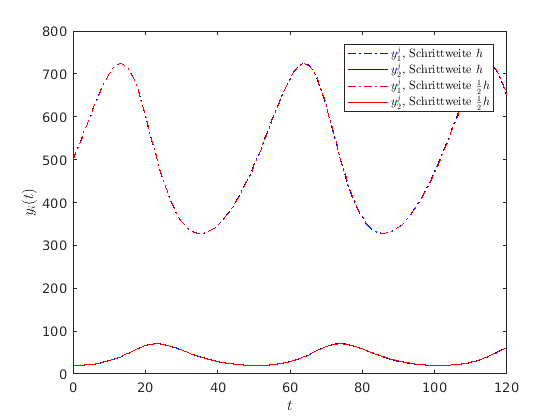

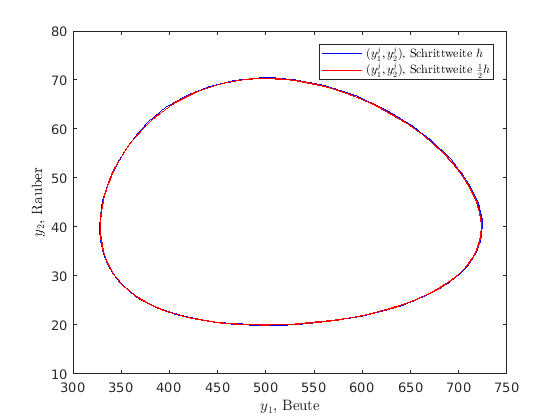

n=120;
for rep=0:1
    n=2^rep*n;
    h=T/n;
    Zeit=0:h:T;
    Y=zeros(n+1,2); Y(1,:)= ystart';
    yalt= ystart; 
    for j=0:n-1      % ein Schritt des verbesserten Euler-Verfahrens
        yzwischen= yalt + 0.5*h*f(yalt,c1,d1,c2,d2);
        yneu= yalt + h*f(yzwischen,c1,d1,c2,d2);
        yalt= yneu;
        Y(j+2,:)= yneu';
    end
    Schrittweite=h
    fprintf('\n Ergebnisse y_1(T), y_2(T) am Endzeitpunkt:\n');
    Resultat=yneu
    disp('----------------');
    plotResults(rep,Zeit,Y); 
end

# Aktivität:

Variieren Sie die Anzahl der Schritte $n$, z.B. $n\in\{30, 60, 120, 1200\}$.

Variieren Sie Parameter, z.B. $c_1 \in\{0.08, 0.8, 1.6\}$,  $d_1 \in \{0.025, 0.0025, 0.001\}$, $d_2 \in \{0.002, 0.01, 0.02\}$.

 Beachte, dass (für $h$ hinreichend klein) die berechnete Lösung periodisch ist. 

function plotResults(rep,Zeit,Y) % Plottet die Ergebnisse
if (rep==0)
    figure(1);
    clf;
    plot(Zeit,Y(:,1),'b-.',Zeit,Y(:,2),'b-');hold on; 
    figure(2); 
    clf;
    plot(Y(:,1),Y(:,2),'b-'); hold on;
end
if (rep==1)
    figure(1);
    plot(Zeit,Y(:,1),'r-.',Zeit,Y(:,2),'r-'); 
    figure(2); 
    plot(Y(:,1),Y(:,2),'r-');   

    figure(1);
    xlabel('$t$','Interpreter','latex'); ylabel('$y_i(t)$','Interpreter','latex');
    leg1=legend('$y_1^j$, Schrittweite $h$','$y_2^j$, Schrittweite $h$',...
       '$y_1^j$, Schrittweite $\frac12 h$','$y_2^j$, Schrittweite $\frac12 h$');
    set(leg1,'Interpreter','latex');
    figure(2);
    xlabel('$y_1$, Beute','Interpreter','latex'); ylabel('$y_2$, Rauber','Interpreter','latex');
    leg2=legend('$(y_1^j,y_2^j)$, Schrittweite $h$','$(y_1^j,y_2^j)$, Schrittweite $\frac12 h$');
    set(leg2,'Interpreter','latex');
end

end

function fout=f(y,c1,d1,c2,d2) % wertet die rechte Seite der DGLn aus
    fout= [c1*y(1)*(1-d1*y(2)); c2*y(2)*(d2*y(1)-1)];
end